# Regression walkthrough: Object-oriented

Before you start, the CANlab_Core_Tools must be added to your path with subfolders. Otherwise, you will get errors. They can be found on Github, here:

[https://github.com/canlab](https://github.com/canlab)

% Sample datasets are in the "Sample_datasets" folder in CANlab_Core_Tools.

This example will use emotion regulation data in the folder: "Wager_et_al_2008_Neuron_EmotionReg"

The dataset is a series of contrast images from N = 30 participants. Each image is a contrast image for [reappraise neg vs. look neg] for one participant.

These data were published in:

Wager, T. D., Davidson, M. L., Hughes, B. L., Lindquist, M. A., Ochsner, K. N.. (2008). Prefrontal-subcortical pathways mediating successful emotion regulation. Neuron, 59, 1037-50.

## Load the dataset

Data found.
Loaded images:
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810001.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810002.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810003.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810004.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810005.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810006.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/con_00810007.img
/Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/Sample_da

Expected 50% of points within 50% normal ellipsoid, found 56.67%
Expected 1.50 outside 95% ellipsoid, found   2

SPM12: spm_check_registration (v6245)              15:12:43 - 03/04/2017
Display /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (

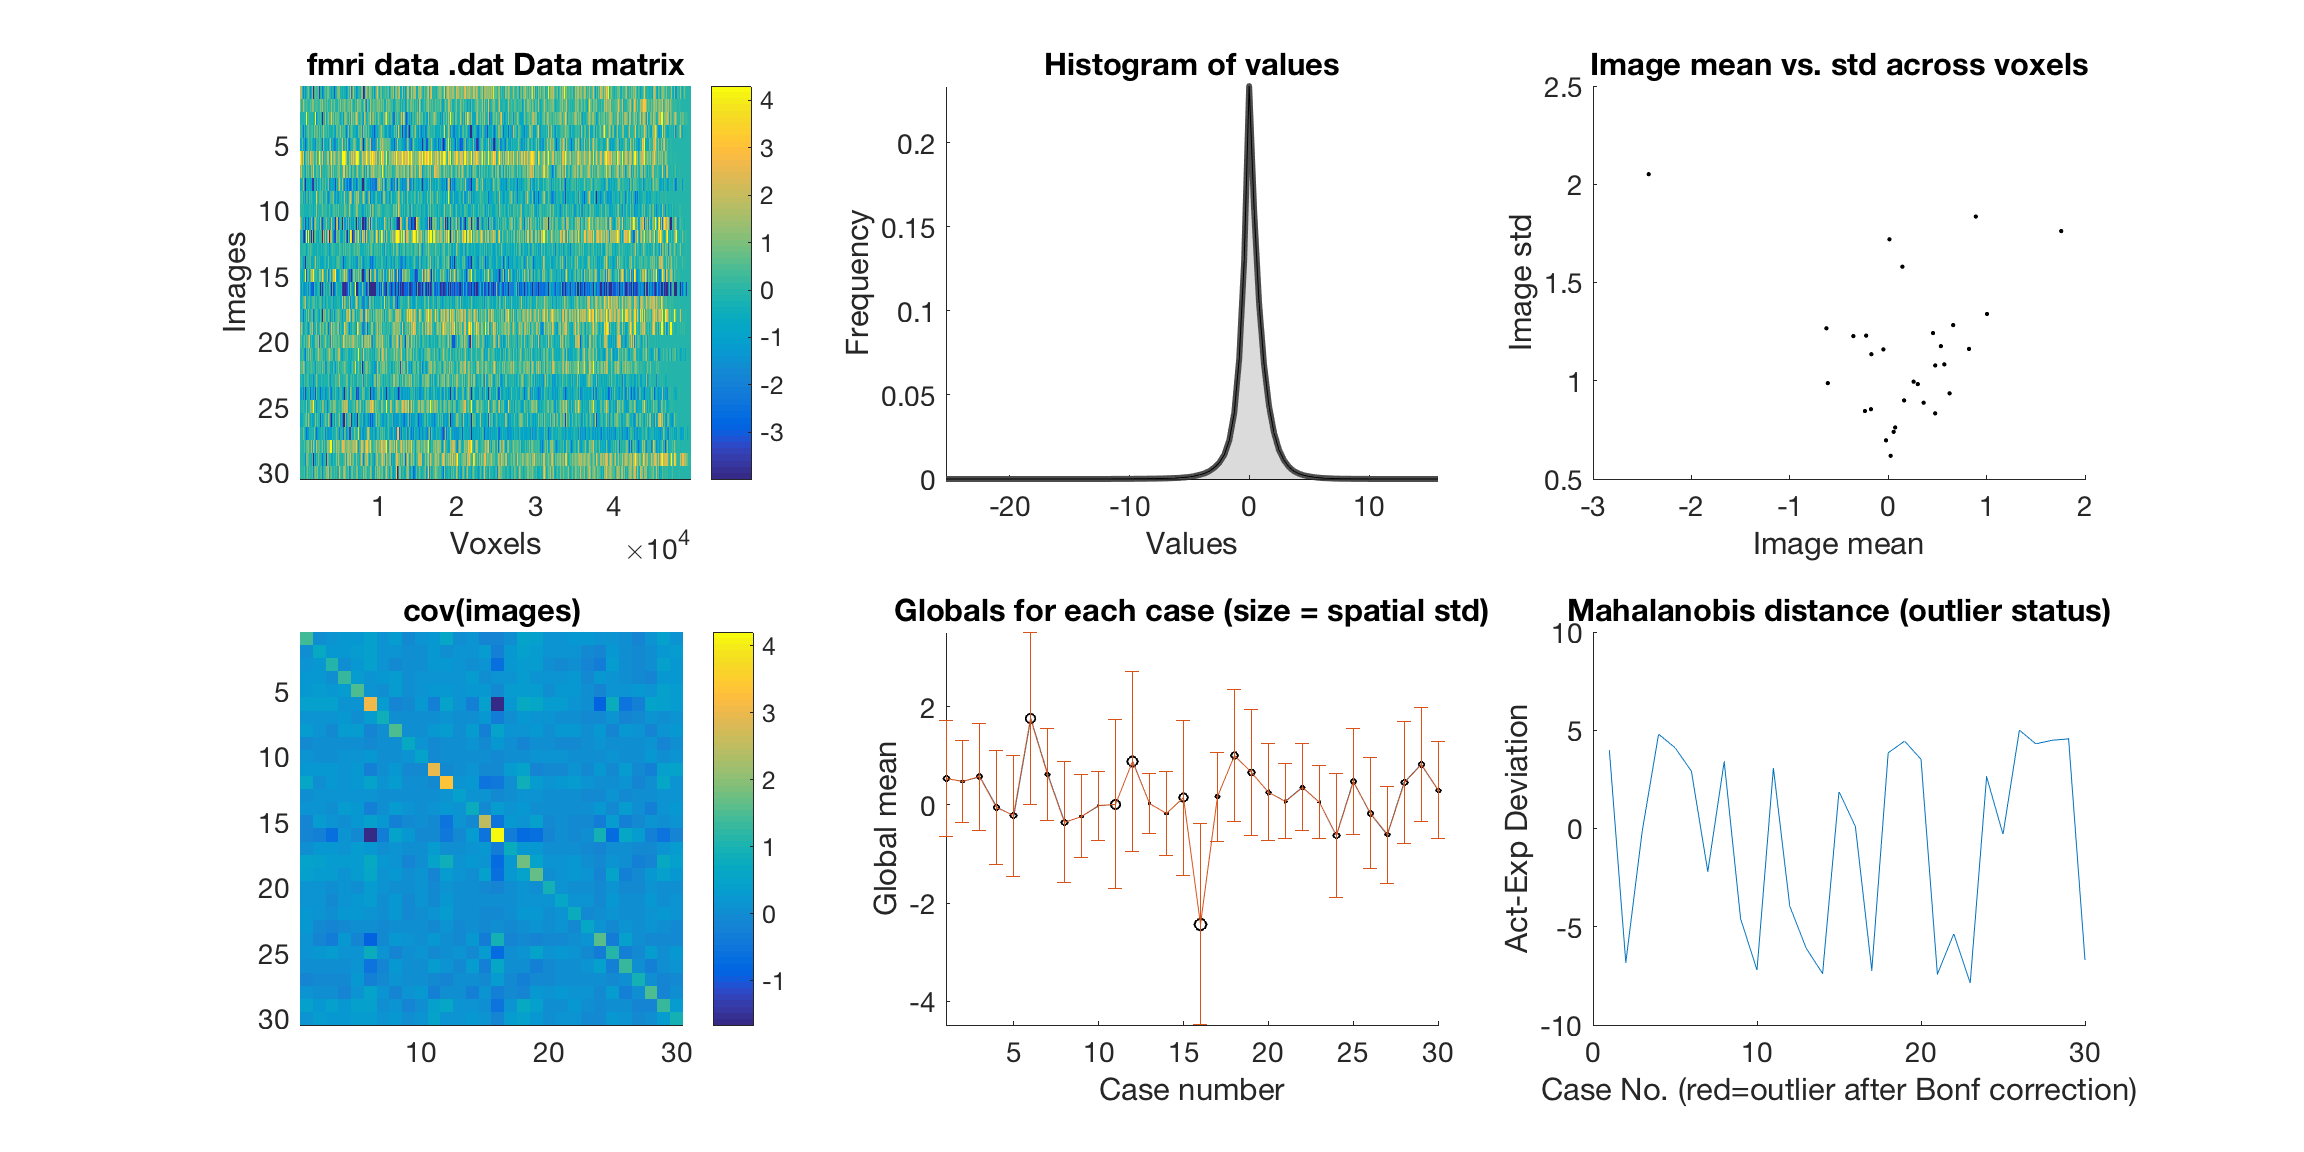


load_a_sample_dataset


% The active line of this script is:
% [data_obj, subject_names, image_names] = load_image_set('emotionreg');

% data_obj is an fmri_data object, with its own methods and properties
%
% to see methods, try methods(data_obj) or methods(fmri_data)



## Load the behavioral data and attach them to the data object


beh_data_file = which('Wager_2008_emotionreg_behavioral_data.txt')
if isempty(beh_data_file), error('Sample behavioral data not found. '); end
beh = readtable(beh_data_file);

% The variable(s) we attach to the data_obj.X field is the design matrix that 
% will be regressed against each voxel when we run the regress.m method

data_obj.X = beh.Y_Reappraisal_Success;



## Check data coverage


SPM12: spm_check_registration (v6245)              18:24:32 - 03/04/2017
Display /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans =     [1×1 struct]


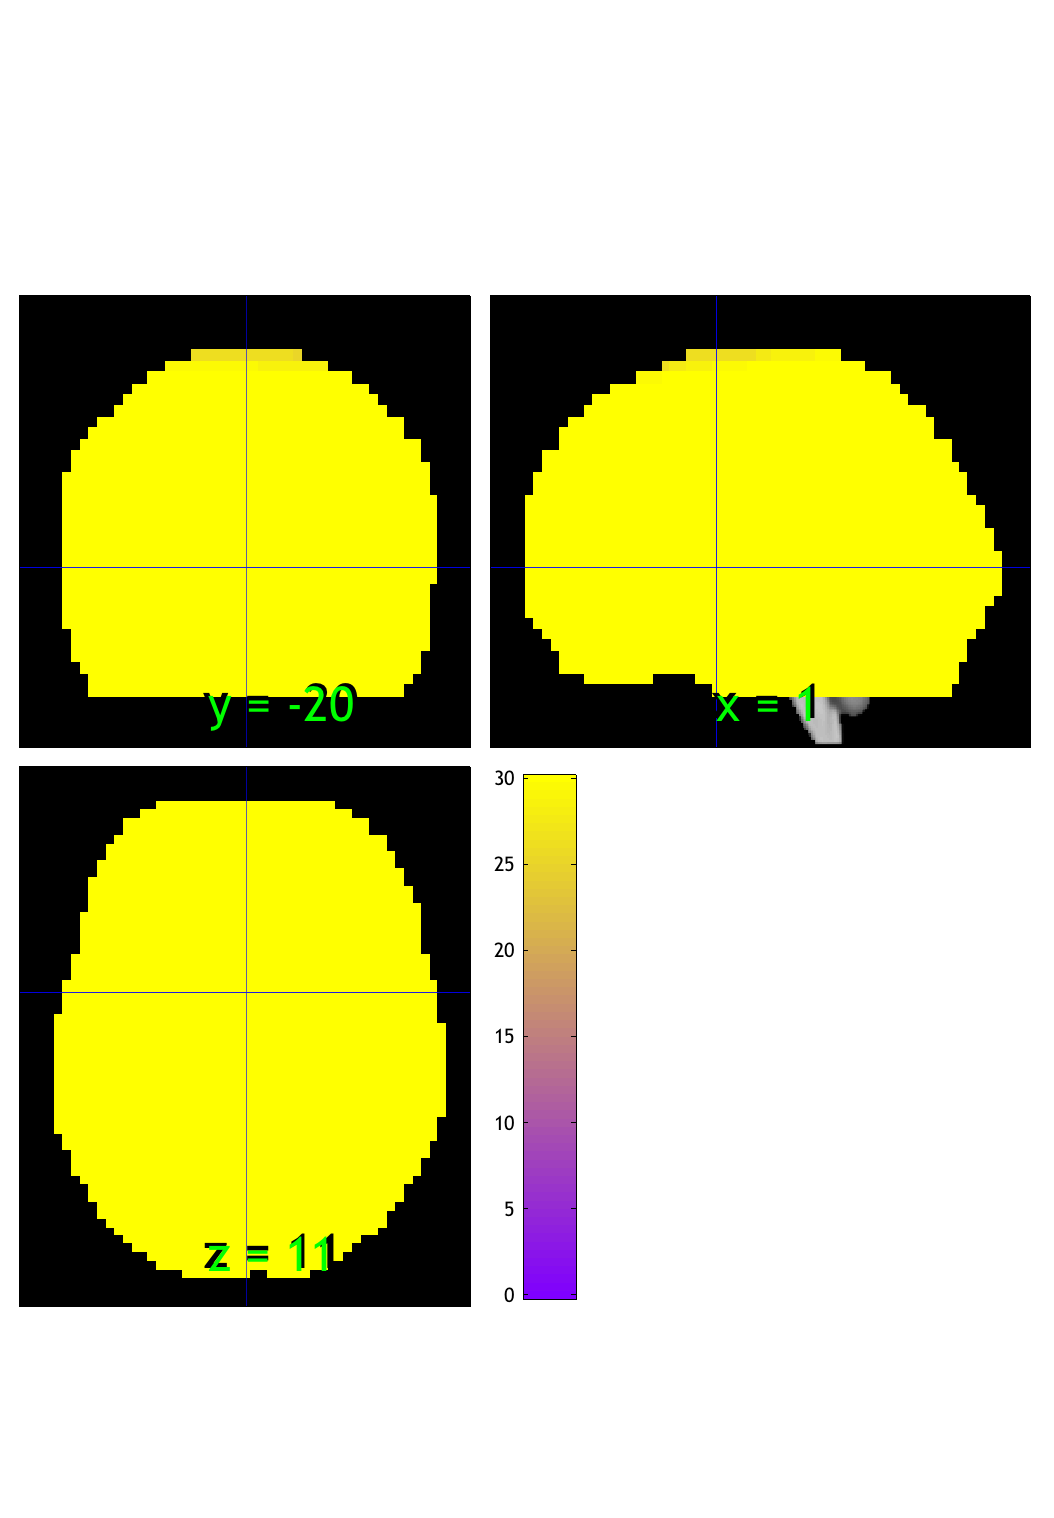


% Check that we have valid data in all voxels for all subjects

% Create a mean image across the 30 contrast images, and store in "m"
% object.  
m = mean(data_obj);

% This next line counts how many subjects have non-zero, non-nan data.
% zero is treated as a missing value.  
% This illustrates how you can do lots of customized things with the data.

m.dat = sum(~isnan(data_obj.dat) & data_obj.dat ~= 0, 2);

% Display on orthviews
%o2 = addblobs(o2, region(m), 'maxcolor', [1 0 0], 'mincolor', [0 0 1]);
orthviews(m, 'trans')

## Run OLS regression


% Run regression with liberal threshold

out = regress(data_obj, .05, 'unc', 'nodisplay');

ans = No intercept detected, adding intercept to last column of design matrix

regression > Y: 49792 voxels. X:   2 obs, 
Predicting Brain Activity from dat.X
Running in OLS Mode
Model run in 0 minutes and 0.06 seconds

Image   1
Positive effect: 9098 voxels, min p-value: 0.00001192
Negative effect: 188 voxels, min p-value: 0.00170541

Image   2
Positive effect: 955 voxels, min p-value: 0.00012028
Negative effect: 3775 voxels, min p-value: 0.00005484


## Set up brain display

Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.


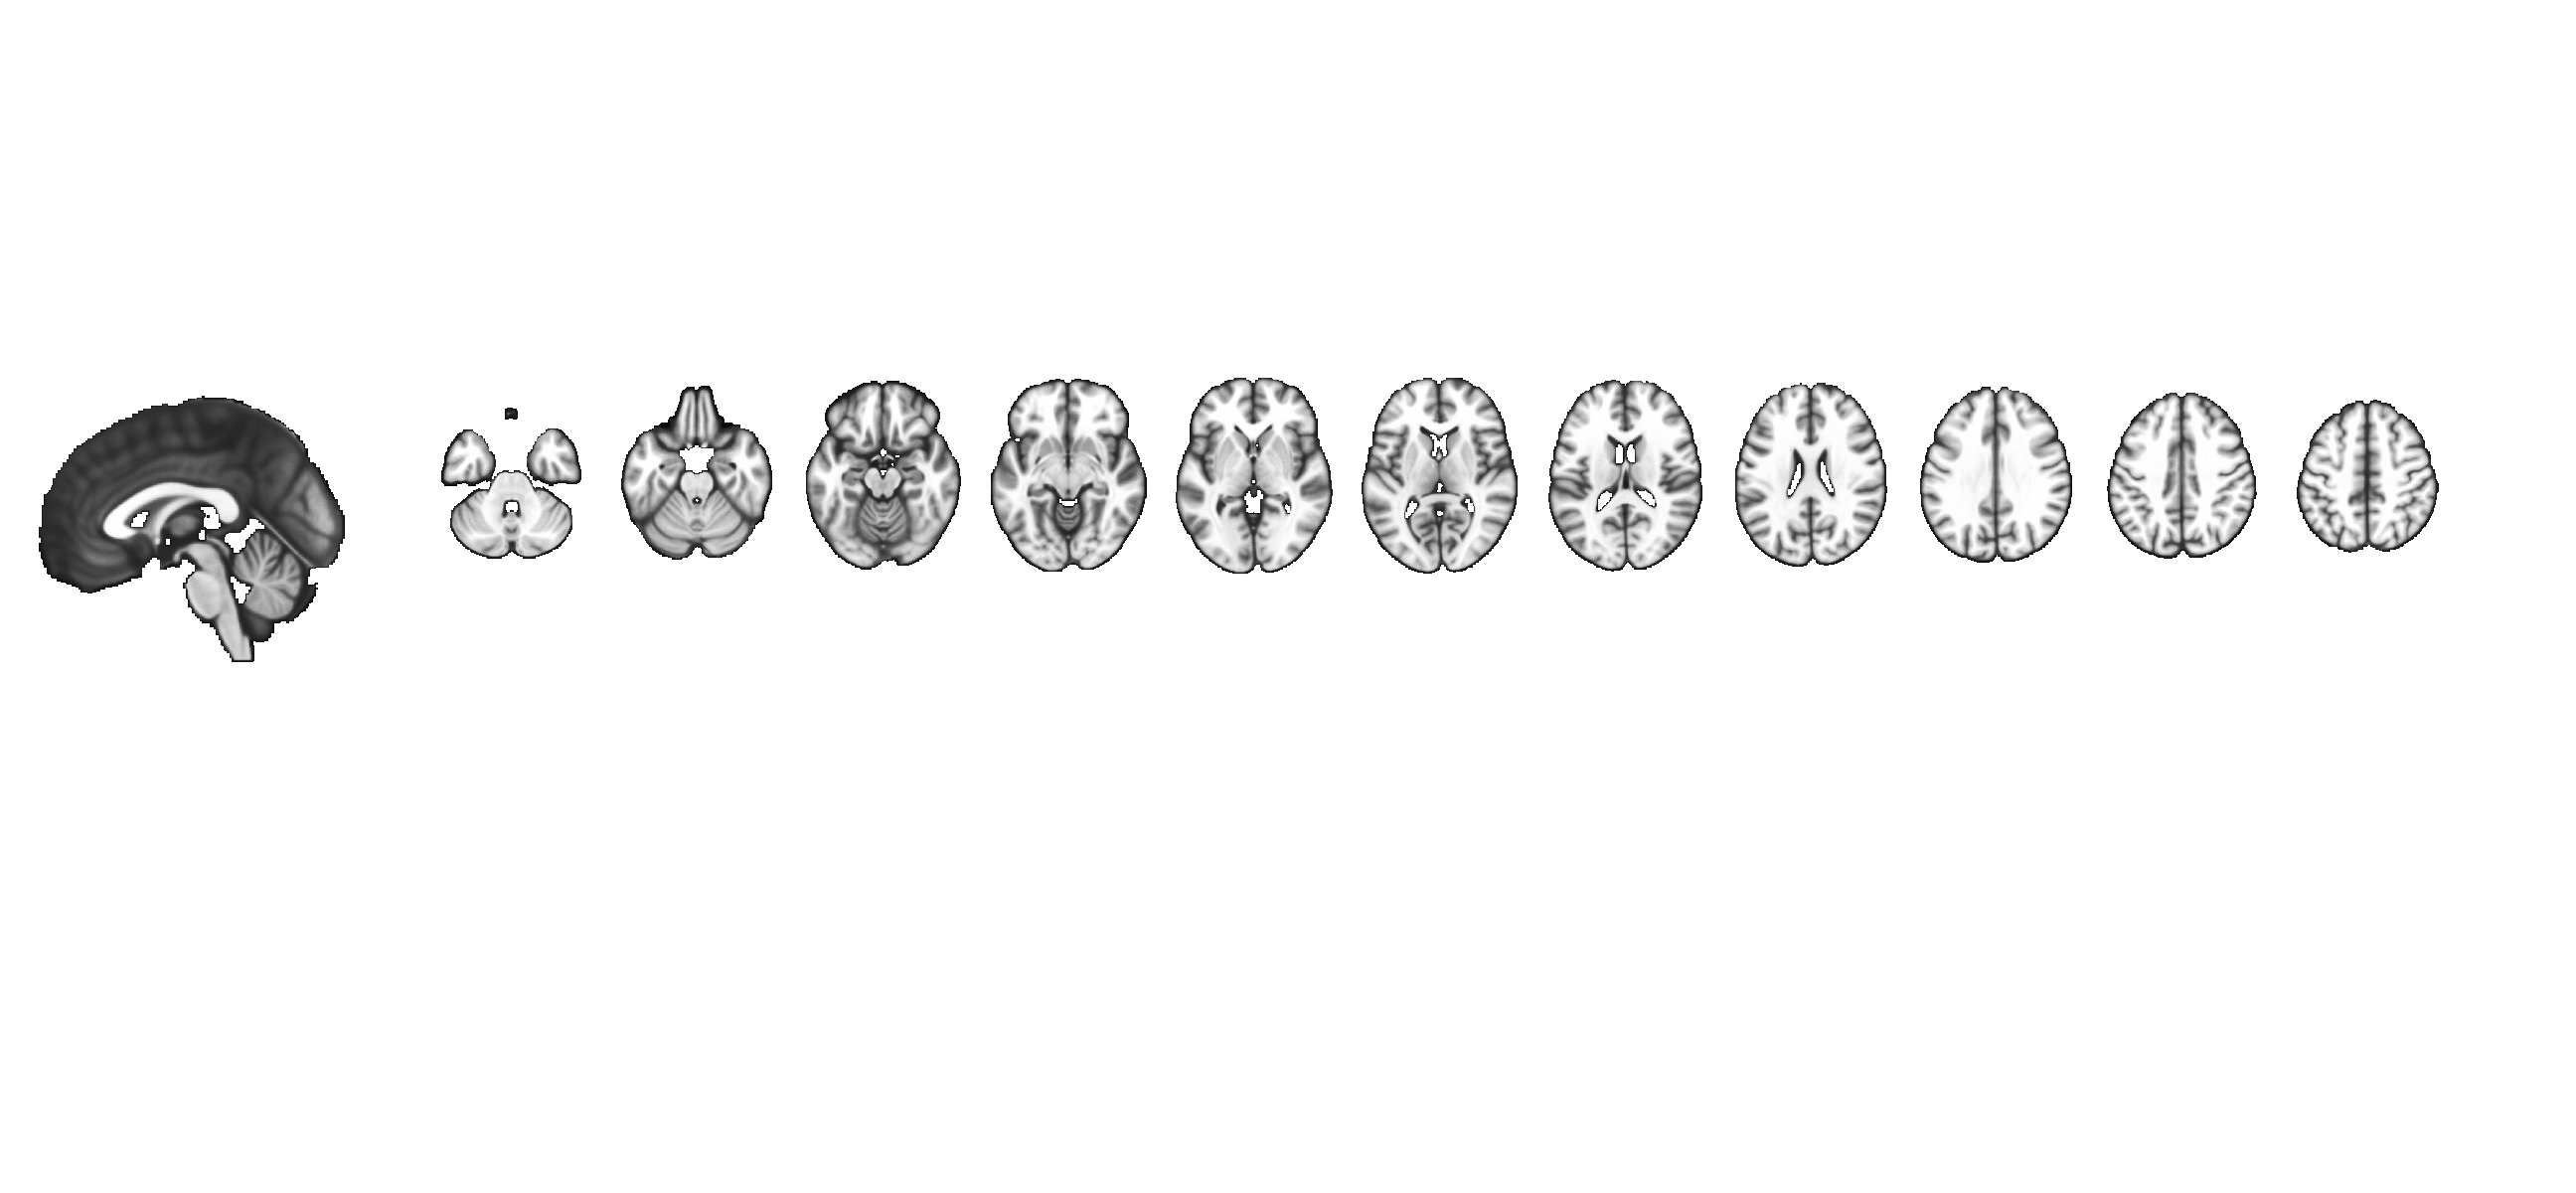


% Load and display an underlay brain.
% o2 is an fmridisplay object.

o2 = canlab_results_fmridisplay([], 'compact2', 'nodisplay');

drawnow, snapnow;


## Display unthresholded results without mask


 % select first t-map: Reapp Success regressor
t = get_wh_image(out.t, 1);

% convert this to a region object
% this object has a vector for each contiguous region.
r = region(t);

Grouping contiguous voxels:  62 regions


axial montage: 3956 voxels displayed, 5330 not displayed on these slices
sagittal montage: 486 voxels displayed, 8800 not displayed on these slices


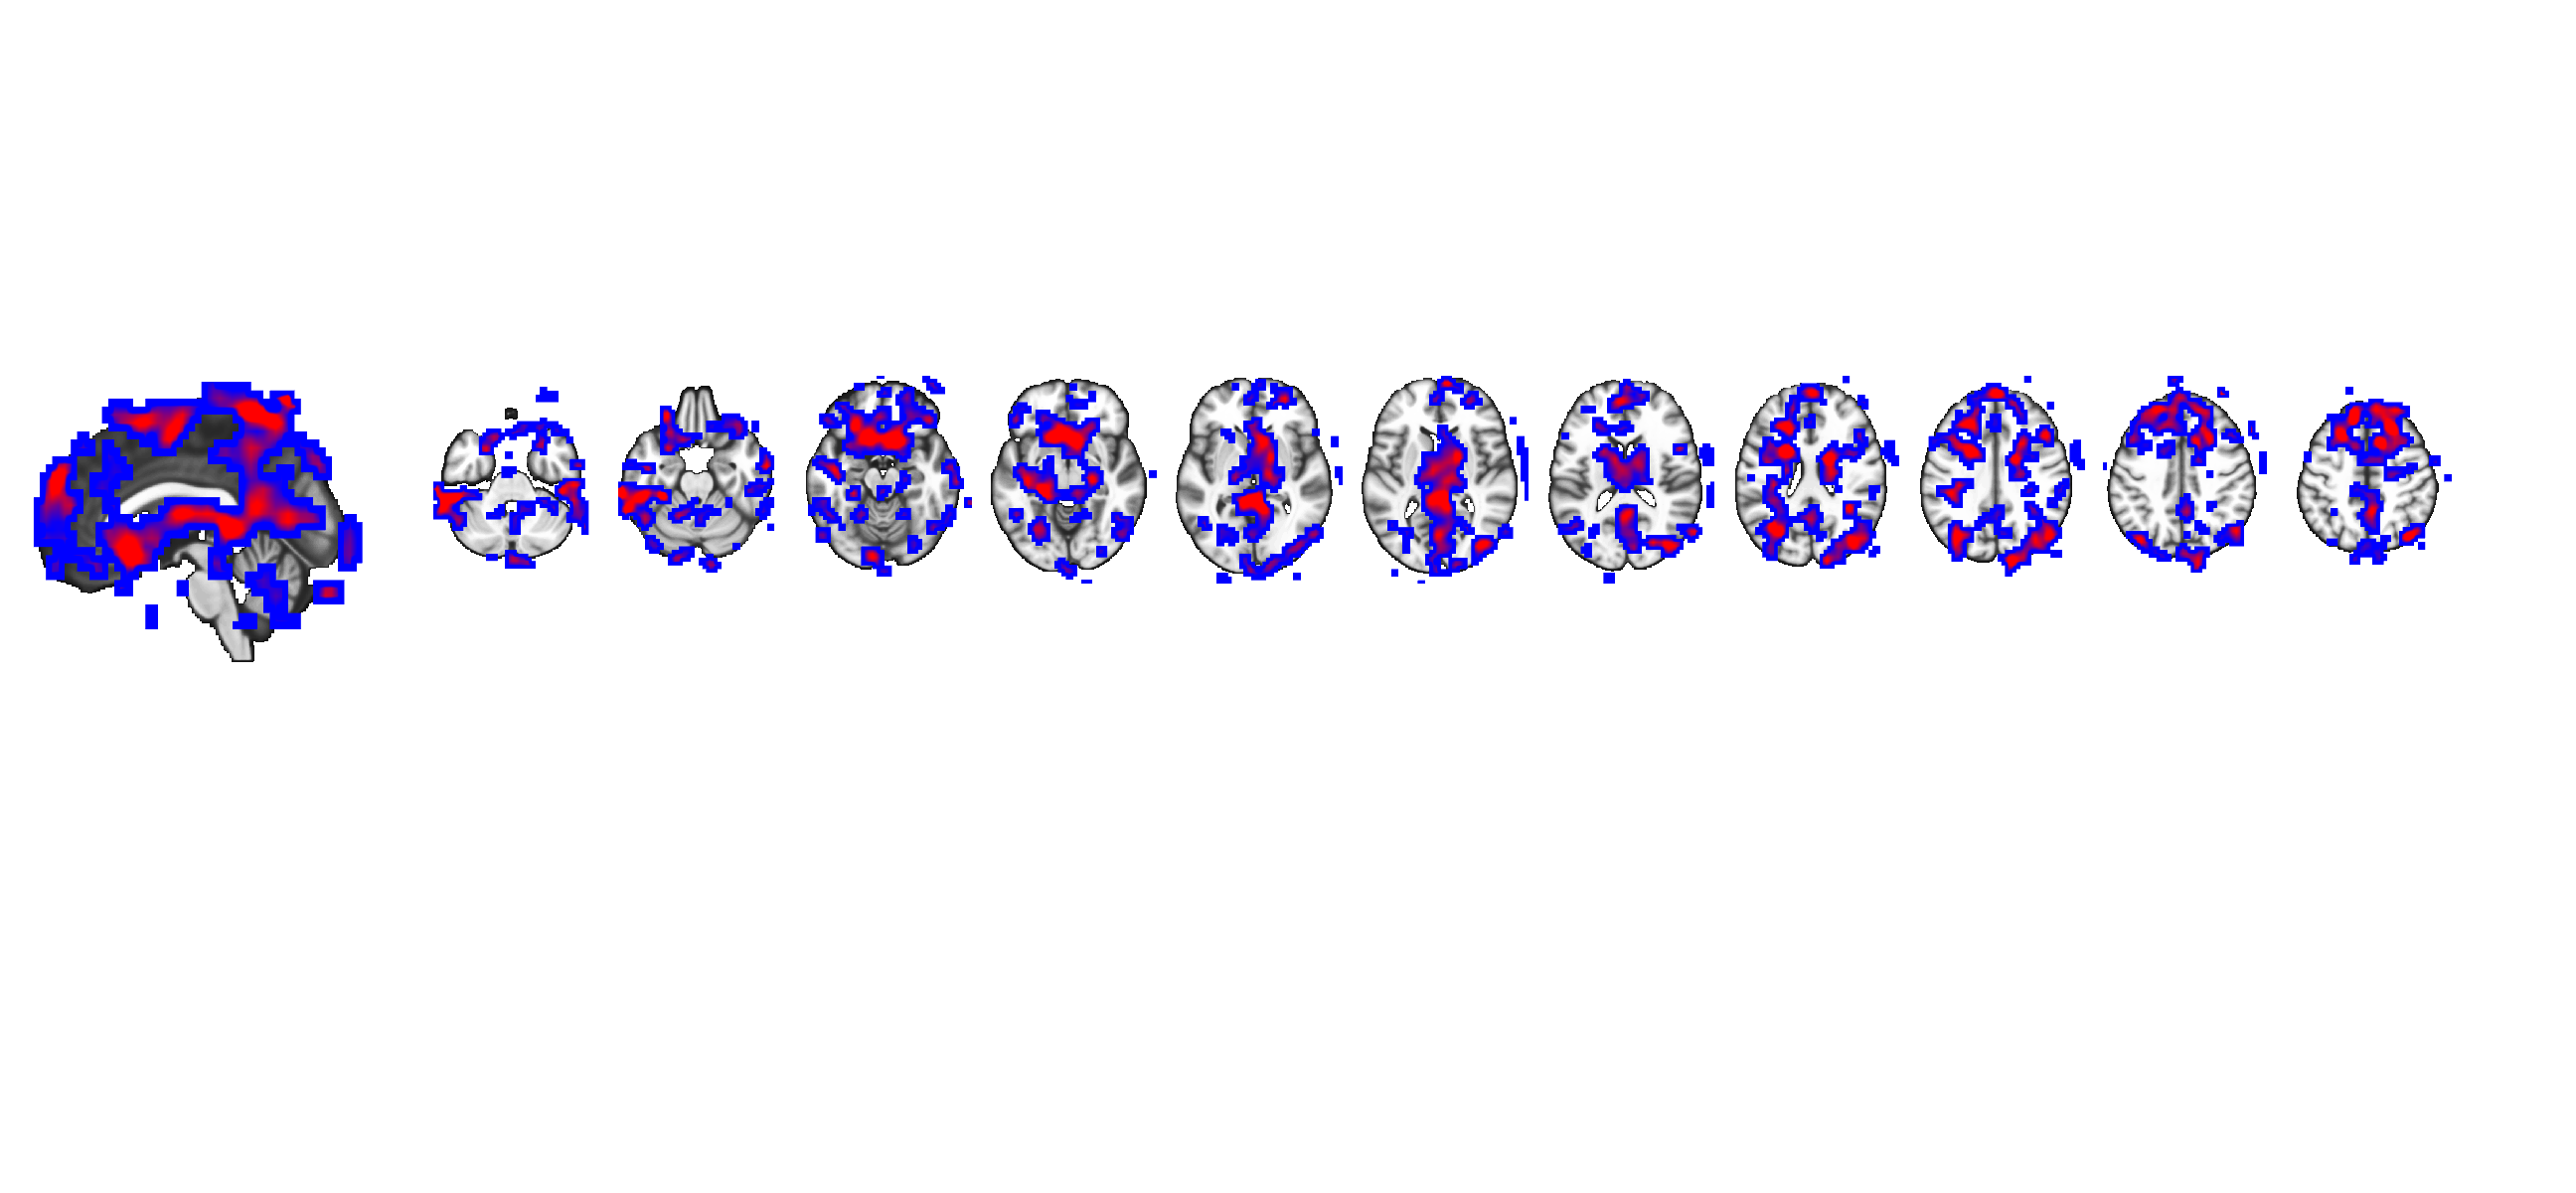


addblobs(o2, r);

## Load a mask, and threshold with FDR within gray matter 

% Load a mask into an fmri_data object

mask = which('gray_matter_mask.img')

mask = /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/gray_matter_mask.img

maskdat = fmri_data(mask);

Using default mask: /Users/tor/Documents/Code_External/spm12/toolbox/FieldMap/brainmask.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1409312 bytes
Loading image number:     0    1
Elapsed time is 0.029468 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.



% Apply the mask to the results
t = apply_mask(t, maskdat);

% Threshold
t = threshold(t, .005, 'unc');


Image   1
Positive effect: 962 voxels, min p-value: 0.00002897
Negative effect:   0 voxels, min p-value: 0.00847960


Grouping contiguous voxels:  52 regions
axial montage: 358 voxels displayed, 604 not displayed on these slices
sagittal montage:  56 voxels displayed, 906 not displayed on these slices


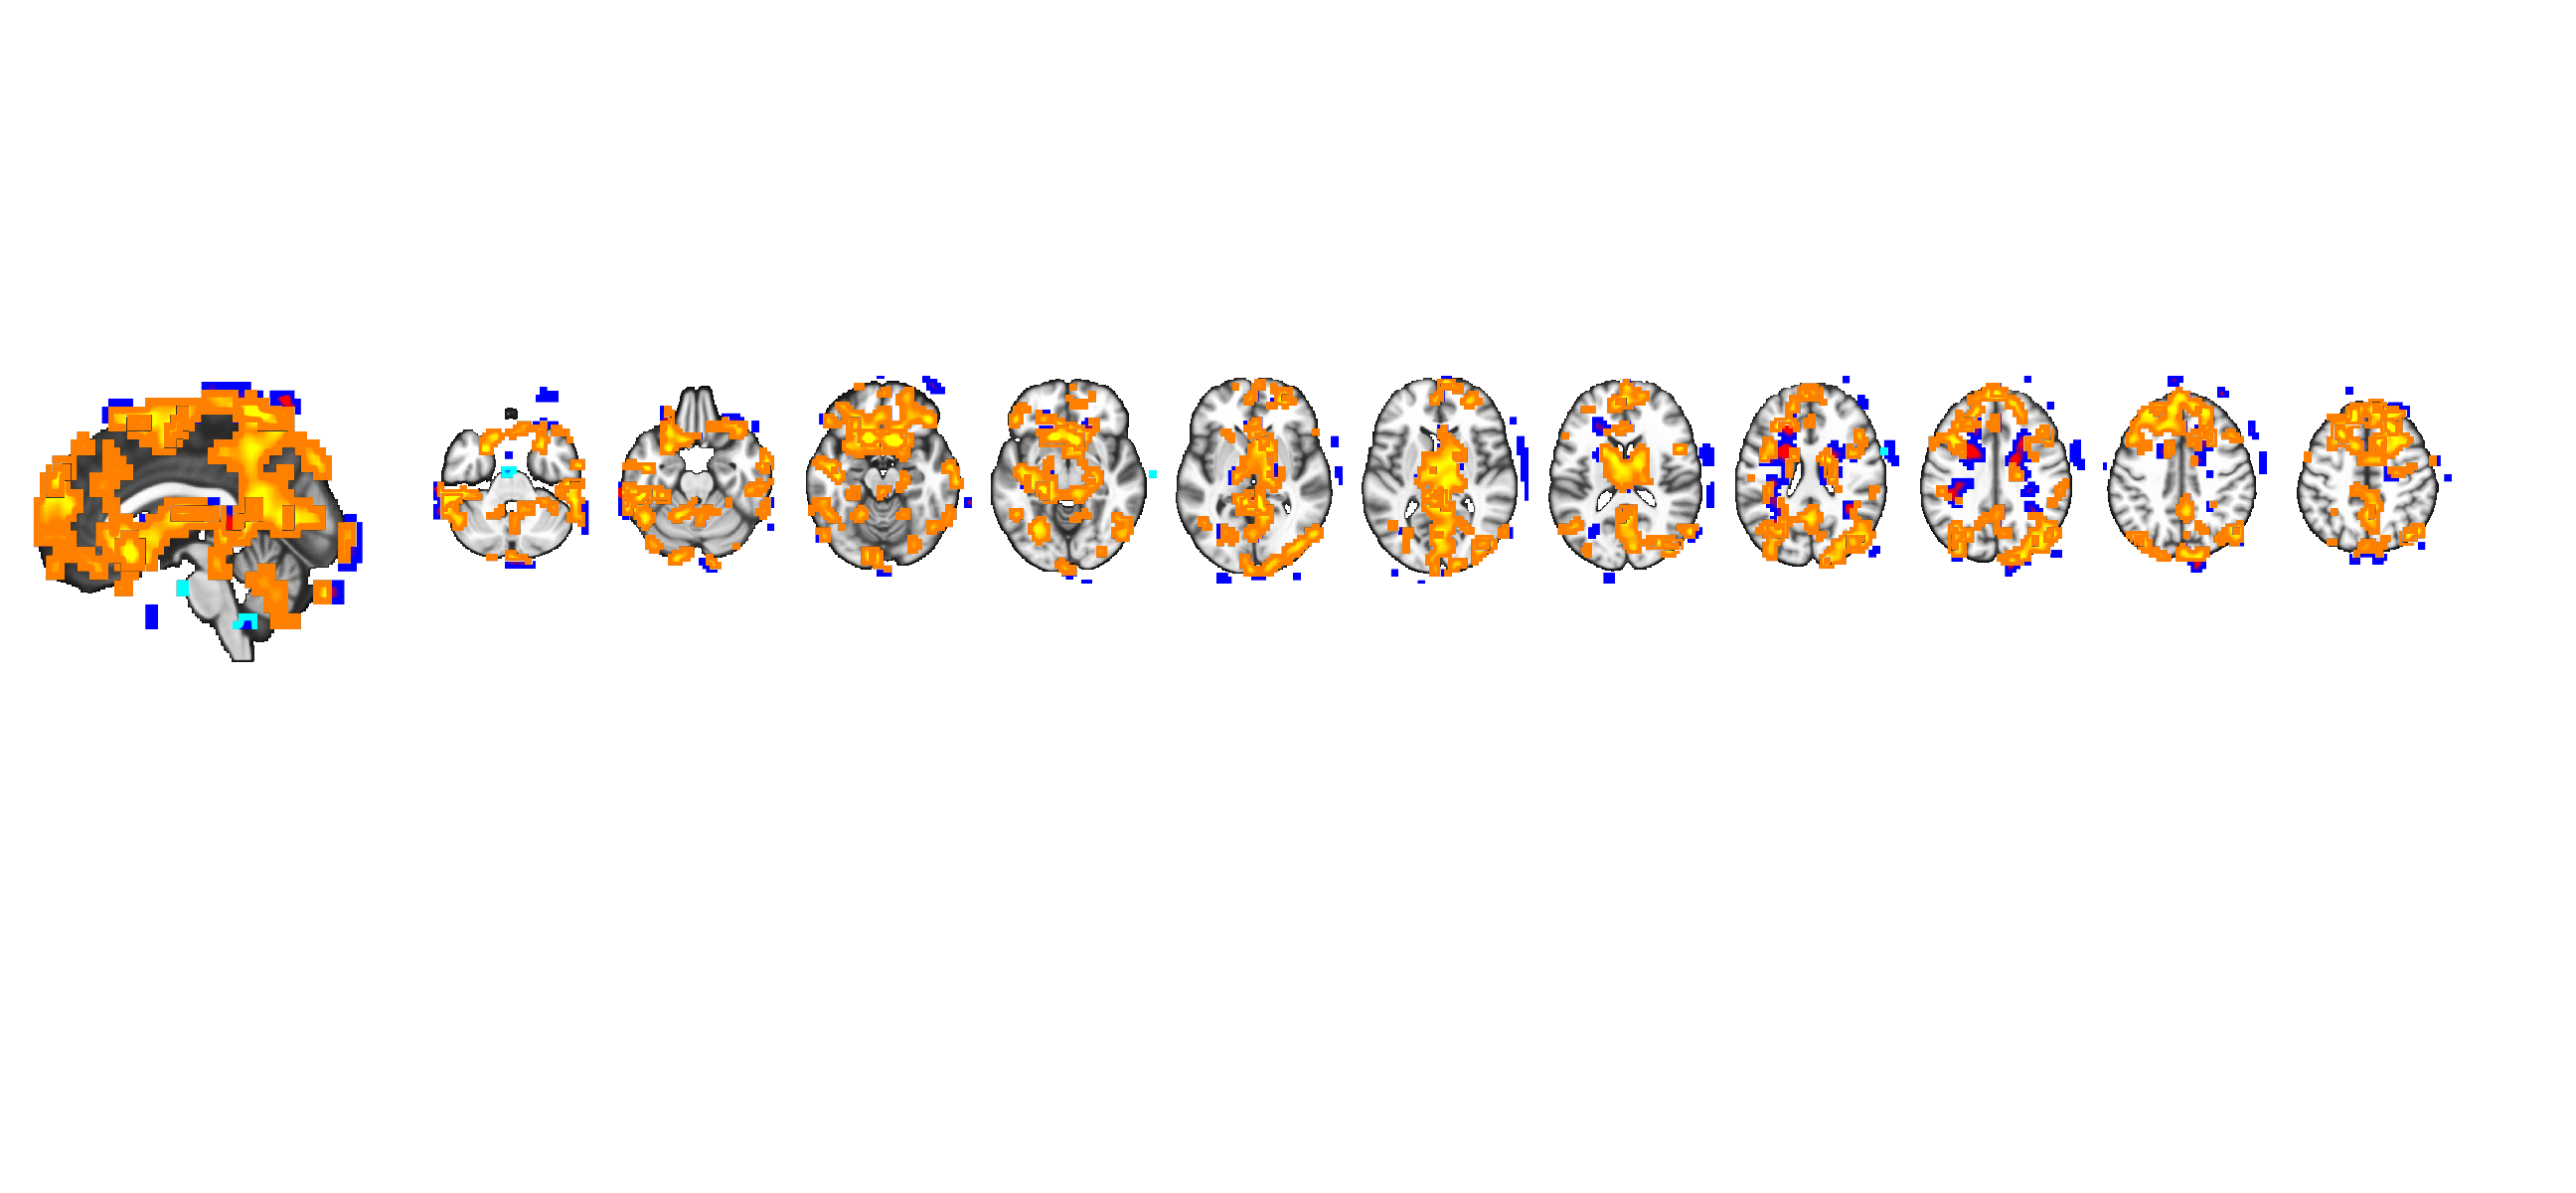


% Remove blobs from the display
o2 = removeblobs(o2);

% Add the new blobs, in a different color
addblobs(o2, region(t), 'splitcolor', {[0 0 1] [0 1 1] [1 .5 0] [1 1 0]});

## Run robust regression

out_robust = regress(data_obj, .05, 'unc', 'robust', 'nodisplay');

ans = No intercept detected, adding intercept to last column of design matrix

regression > Y: 49792 voxels. X:   2 obs, 
Predicting Brain Activity from dat.X
Running in Robust Mode


Model run in 1 minutes and 30.18 seconds

Image   1
Positive effect: 7056 voxels, min p-value: 0.00000000
Negative effect: 486 voxels, min p-value: 0.00002585

Image   2
Positive effect: 1721 voxels, min p-value: 0.00000120
Negative effect: 3251 voxels, min p-value: 0.00000002


## Display robust regression results

% Normally, we need only remove blobs; in this interactive script, we need to recreate the slice montage
o2 = removeblobs(o2);

Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.


o2 = canlab_results_fmridisplay([], 'compact2', 'nodisplay');

t = out_robust.t;

t = apply_mask(t, maskdat);
t = threshold(t, .005, 'unc');


Image   1
Positive effect: 1311 voxels, min p-value: 0.00000000
Negative effect:  67 voxels, min p-value: 0.00002585

Image   2
Positive effect: 279 voxels, min p-value: 0.00000120
Negative effect: 623 voxels, min p-value: 0.00000002


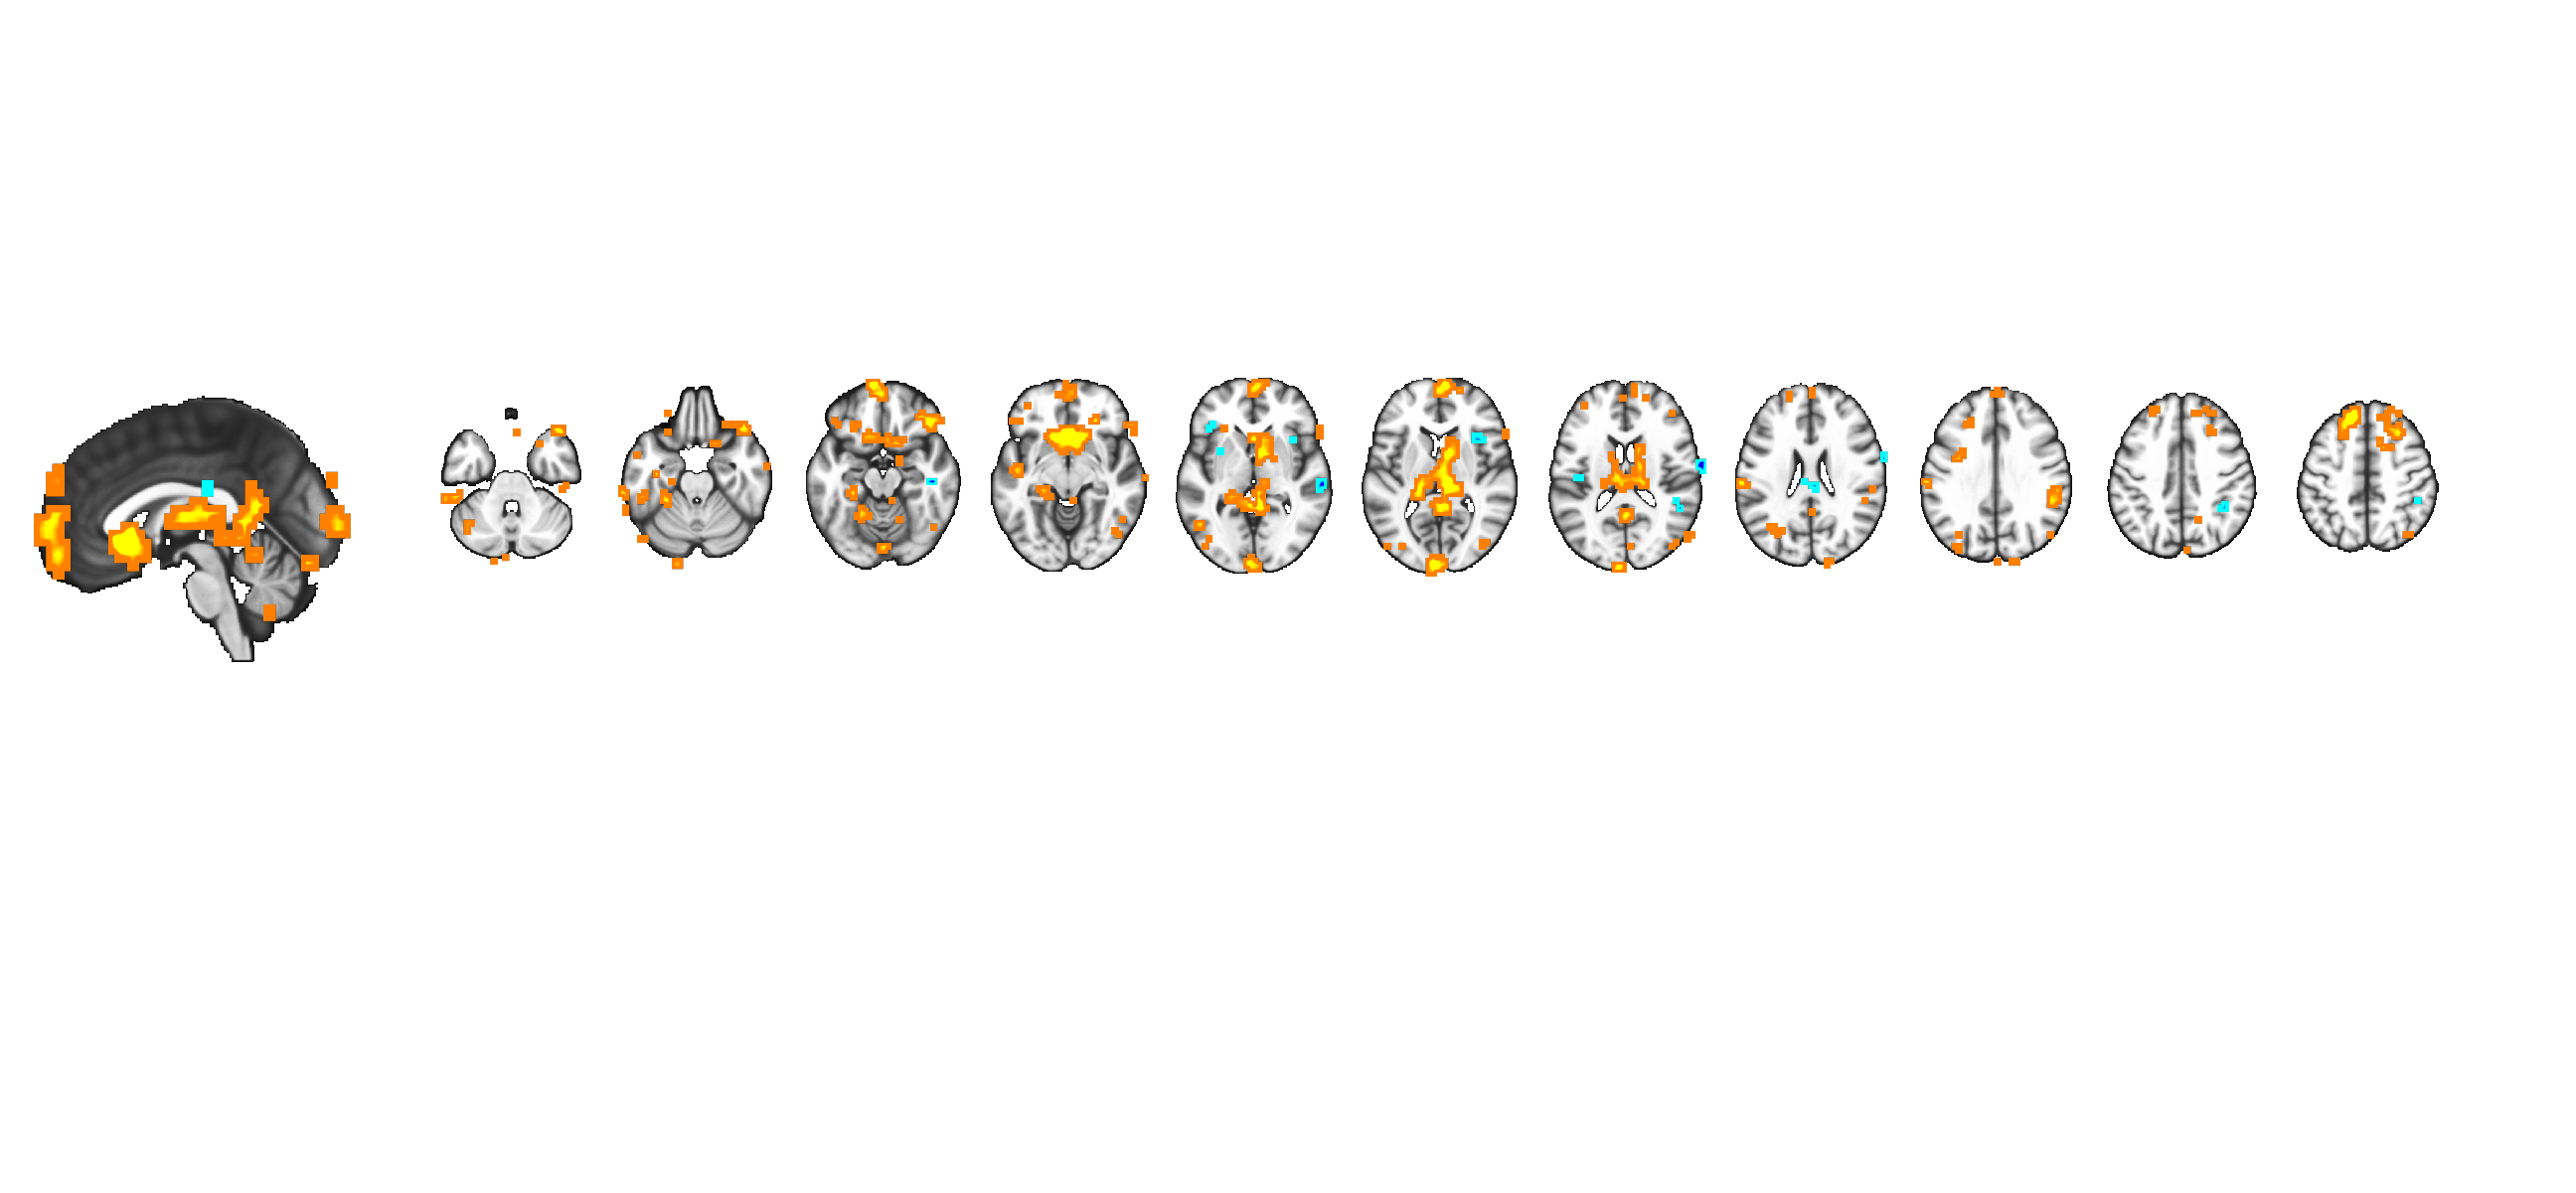

Grouping contiguous voxels: 123 regions
axial montage: 710 voxels displayed, 668 not displayed on these slices
sagittal montage: 100 voxels displayed, 1278 not displayed on these slices


o2 = removeblobs(o2);
addblobs(o2, region(t), 'splitcolor', {[0 0 1] [0 1 1] [1 .5 0] [1 1 0]});

% Normally, we need only remove blobs; in this interactive script, we need to recreate the slice montage
o2 = removeblobs(o2);
o2 = canlab_results_fmridisplay([], 'compact2', 'nodisplay');

Setting up fmridisplay objects
This takes a lot of memory, and can hang if you have too little.



t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.000472

Image   1
Positive effect: 314 voxels, min p-value: 0.00000000
Negative effect:  10 voxels, min p-value: 0.00002585
Image   2 FDR q < 0.050 threshold is 0.000073

Image   2
Positive effect:  23 voxels, min p-value: 0.00000120
Negative effect:  51 voxels, min p-value: 0.00000002


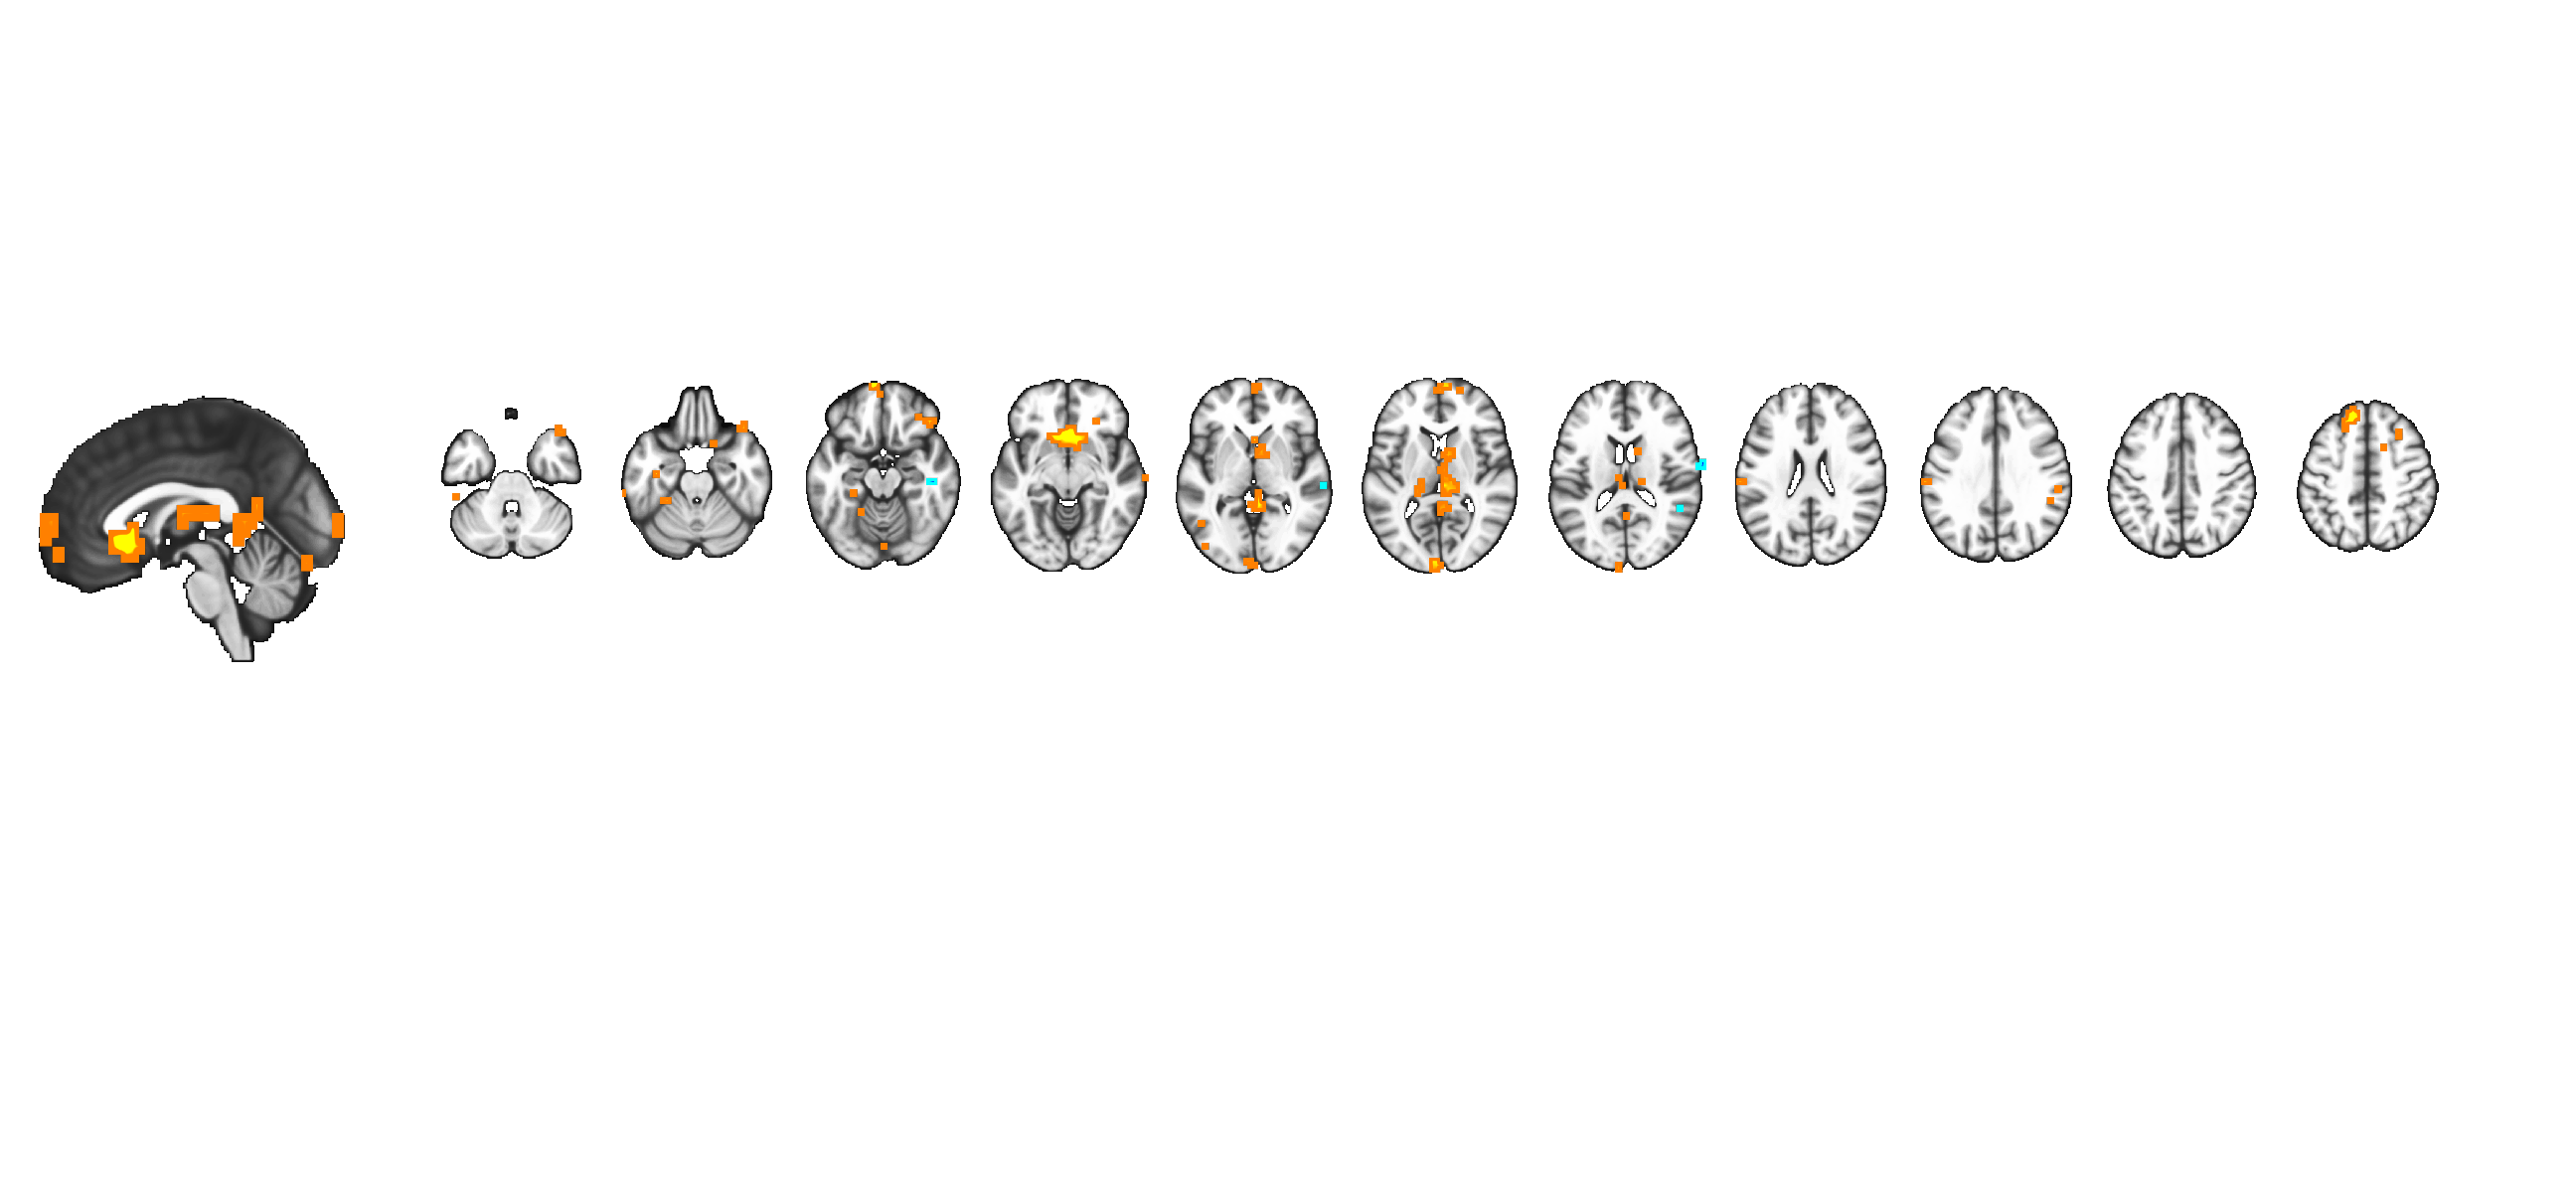

Grouping contiguous voxels:  48 regions
axial montage: 169 voxels displayed, 155 not displayed on these slices
sagittal montage:  35 voxels displayed, 289 not displayed on these slices


o2 = removeblobs(o2);
addblobs(o2, region(t), 'splitcolor', {[0 0 1] [0 1 1] [1 .5 0] [1 1 0]});

## Extract data from each significant region and plot


% Get a region object with average data from each significant contiguous cluster
% r_with_data.dat field has region average
% r_with_data.all_data has all voxel values

r_with_data = extract_roi_averages(data_obj, t, 'contiguous_regions');

fmri_data.extract_roi_averages: Defining mask object. 
Grouping contiguous voxels:  48 regions
Averaging data. Done.



% Remove regions smaller than 10 voxels 
r_with_data(cat(1, r_with_data.numVox) < 10) = [];

% Show regions
colors = scn_standard_colors(length(r_with_data));
orthviews(r_with_data, colors)


SPM12: spm_check_registration (v6245)              03:07:43 - 04/04/2017
Display /Users/tor/Documents/Code_Repositories/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1



% Print table of colors
region_num = (1:length(r_with_data))';
colorsmatrix = cat(1, colors{:});
color_table = table(region_num, colorsmatrix);
disp(color_table);

    region_num    colorsmatrix
    __________    ____________

    1             1    0    0 
    2             0    1    0 
    3             0    0    1 
    4             1    1    0 
    5             1    0    1 
    6             0    1    1 



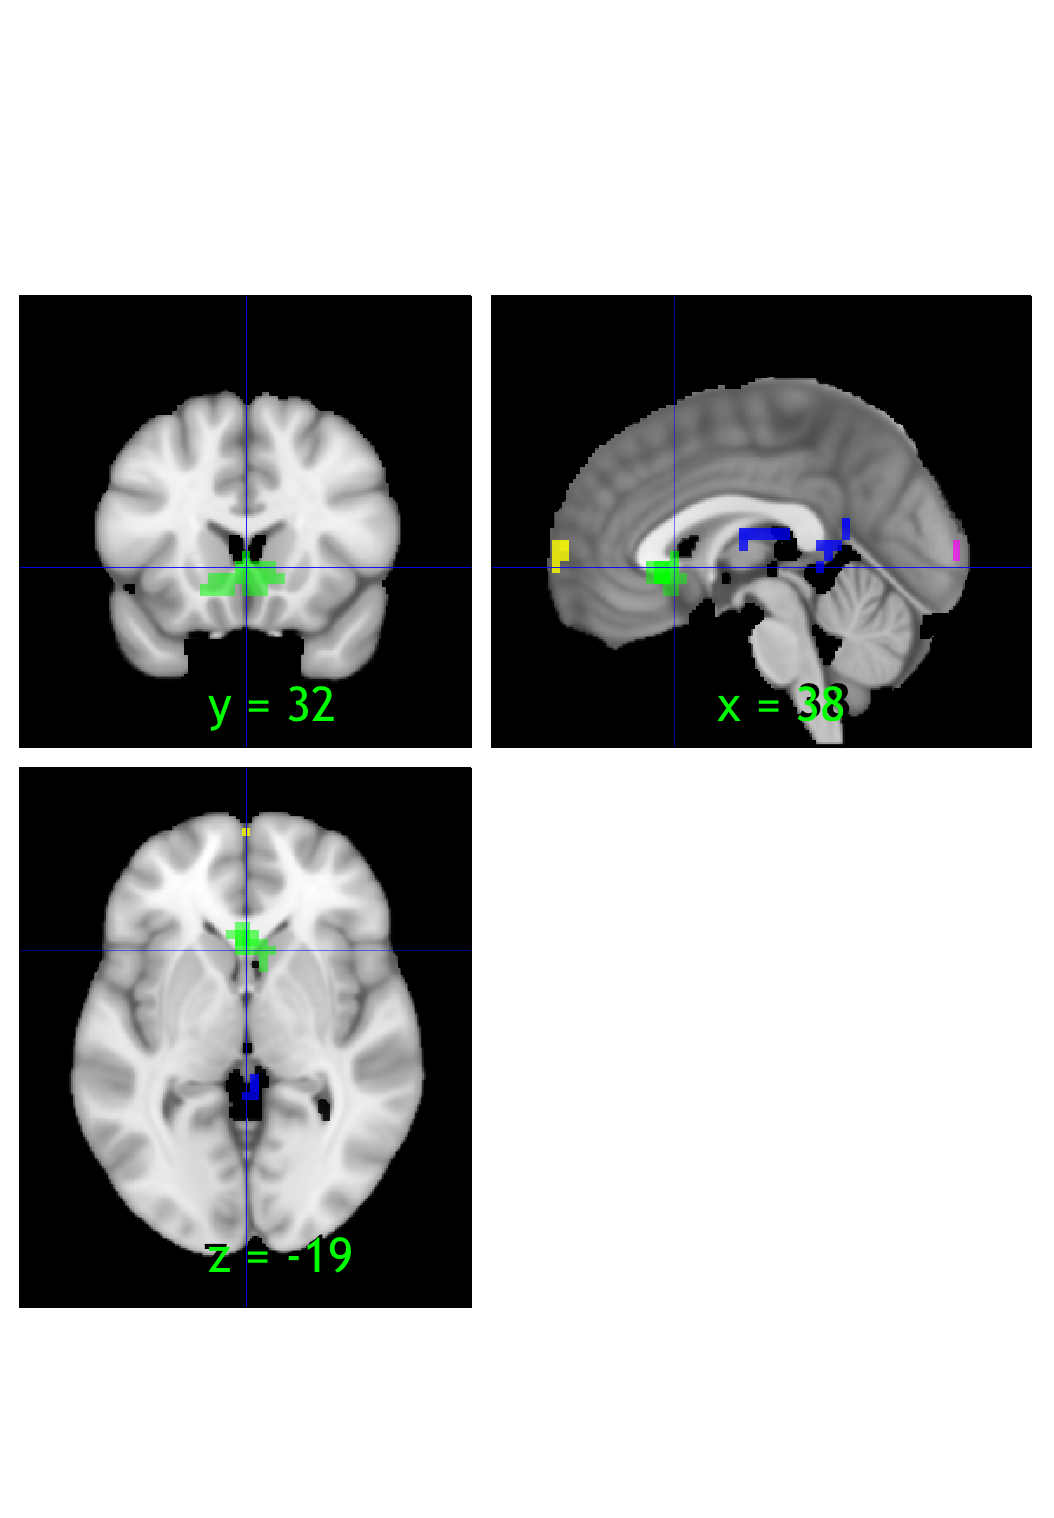


whregion = 2;
spm_orthviews('Reposition', r_with_data(whregion).mm_center);

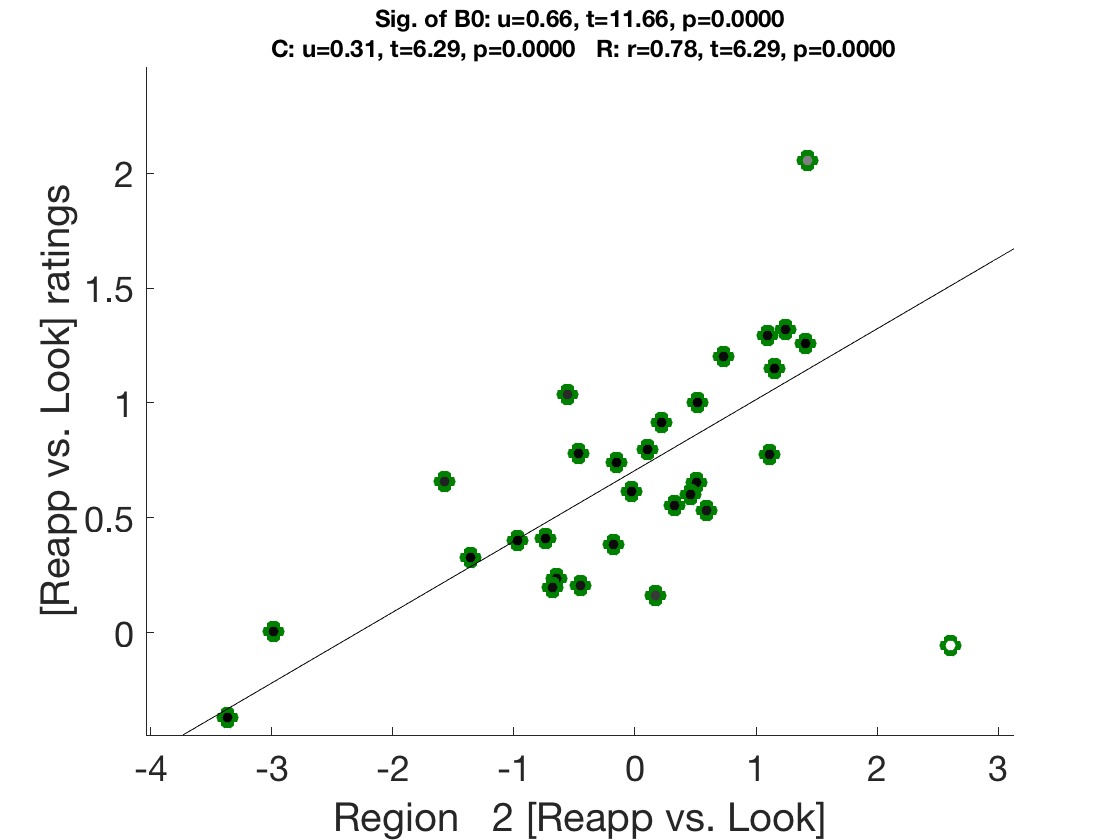

create_figure('scatterplot');
[r,infostring,sig,h] = plot_correlation_samefig(r_with_data(whregion).dat, data_obj.X, [], 'bo', false, true);
xlabel(sprintf('Region %3.0f [Reapp vs. Look]', whregion))
ylabel('[Reapp vs. Look] ratings');
set(h, 'Color', colors{whregion} ./ 2, 'LineWidth', 2);